# Projecte de Visió: Detecció i interpretació de partitures

*Per Pau Torras (1495172) i Marc Espinosa (1495036)*

L'objectiu no és, ni molt menys, ser capaç de llegir una partitura "real", en el sentit que aquestes poden arribar a ser extraordinariament complicades i la flexibilitat del llenguatge en quant a emplaçament i diversitat de fórmules equivalents juga en contra dels interessos d'un algorisme generalitzat.

És així que de moment ens basarem en imatges sense perspectiva i ens centrarem en aquells aspectes de visió que ens permetin extreure la informació exclusivament musical. Per això hem generat un joc de partitures molt simples amb creixent nivell de recursos musicals. Aquestes inclouen, en ordre de creixent complexitat:

- Notes rodones

- Notes blanques

- Alteracions cromàtiques (per diferenciar-les millor només hem inclòs sostinguts, donat que la forma similar dels bemolls a les notes blanques poden donar problemes)

- Notes negres

- Acords

El cas particular **testbed_x00dpi.png** és una partitura de prova amb aquests paràmetres en ment.

També tenim una secció amb corxeres i armadures, però això ho considerem com a extra, perquè la unió entre notes i la interpretació de valors de pulsació pot esdevenir massa complicada.

Aquest projecte està inspirat en el següent paper: [http://vision.stanford.edu/teaching/cs231a_autumn1213_internal/project/final/writeup/distributable/sdMiller_Paper.pdf](http://vision.stanford.edu/teaching/cs231a_autumn1213_internal/project/final/writeup/distributable/sdMiller_Paper.pdf)

A més de la tasca en OCR que desenvolupen alguns equips del CVC.

S'implementarà únicament amb tècniques de visió clàssiques i, en la mesura de les nostres possibilitats, emprant únicament aquelles que s'hagin vist a les sessions de teoria.

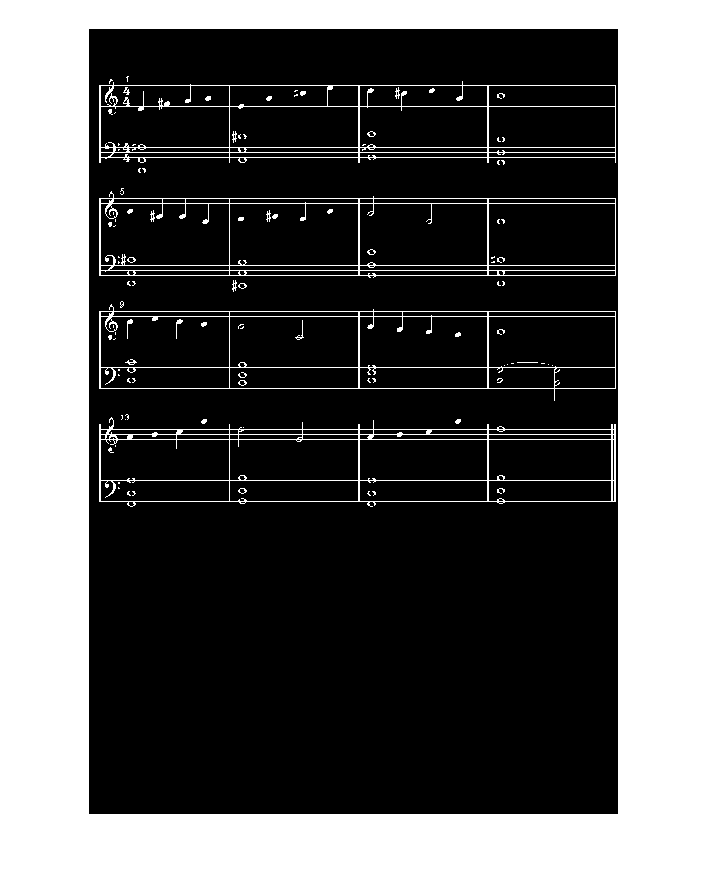

close all; clearvars; clc;

score_base = imread("../input/custom_300dpi.png");
score_base = 255 - rgb2gray(score_base);
score_size = size(score_base);

score_thresh = graythresh(score_base);
score_base = score_base > score_thresh;

figure, imshow(score_base, []);

Fem la derivada de la imatge en sentit vertical i binaritzem el resultat de manera de que només ens quedem amb els gradents creixents

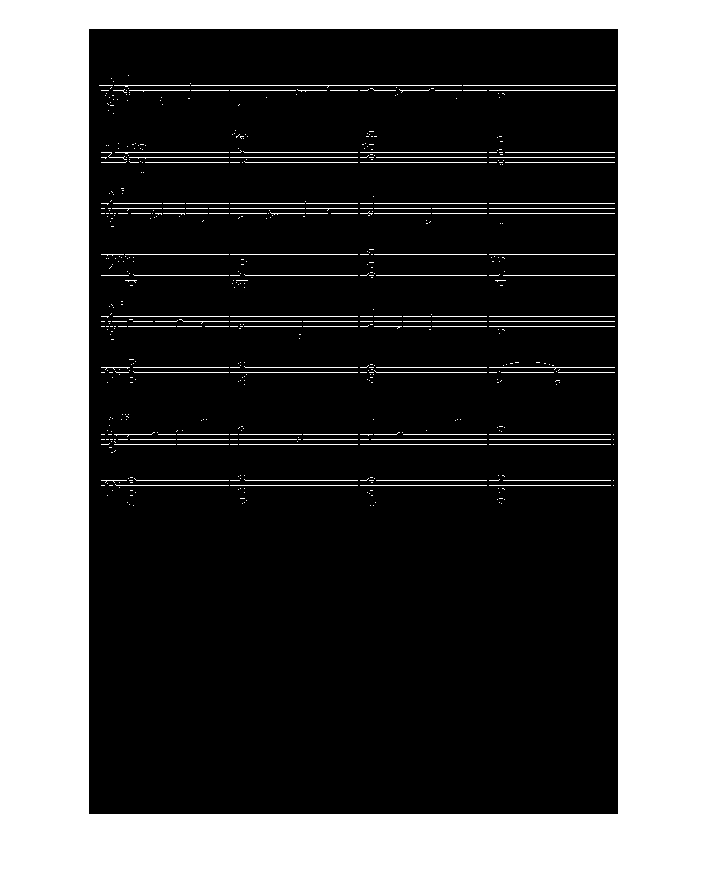

derivada_v = conv2(score_base, [2 0 -2]', 'same') > 0.5;
derivada_v(1,:) = 0;

figure, imshow(derivada_v, []);

Processem la imatge per amagar el soroll fruit de les línies verticals que s'han perdut amb el procés de thresholding. Les mides dels elements estructurants van íntimament relacionades amb la resolució de la imatge. De moment i de manera arbitrària ens basem en els exemples d'uns 300 píxels per polzada (considerant les imatges d'entrada DIN-A4)

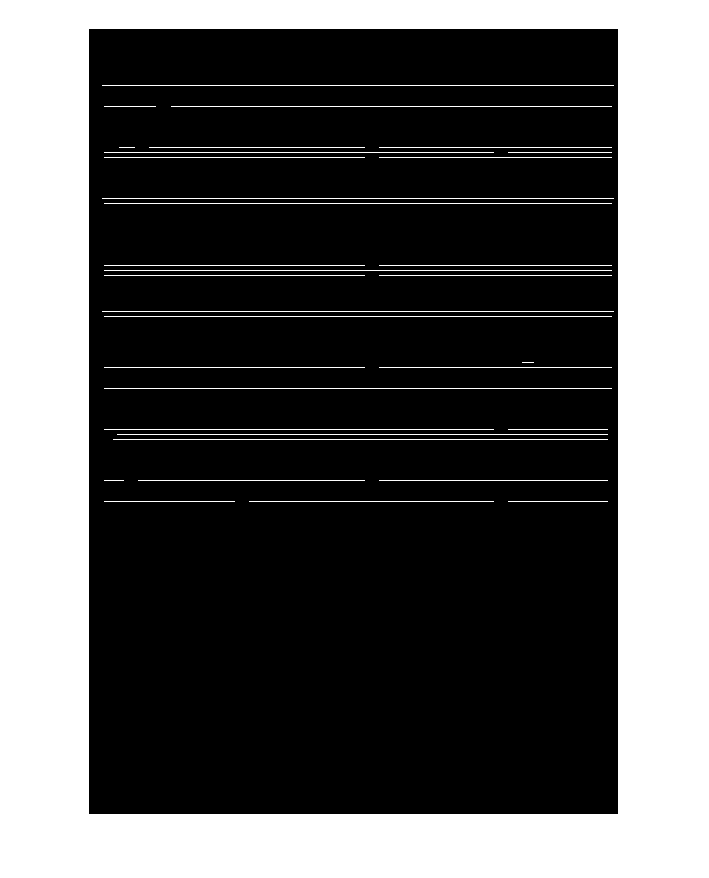

B = strel('line', 5, 0);                
derivada_v = imdilate(derivada_v, B);   % Minimitzar la mida dels forats de les notes

B = strel('line', 25, 0);
derivada_v = imerode(derivada_v, B);    % Eliminar agents foranis que no siguin línies

B = strel('line', 50, 0);
derivada_v = imclose(derivada_v, B);    % Reconnectar les línies

derivada_v = imtranslate(derivada_v, [0, 1], 'nearest');

derivada_v = medfilt2(derivada_v, [3,3]);

figure, imshow(derivada_v, []);

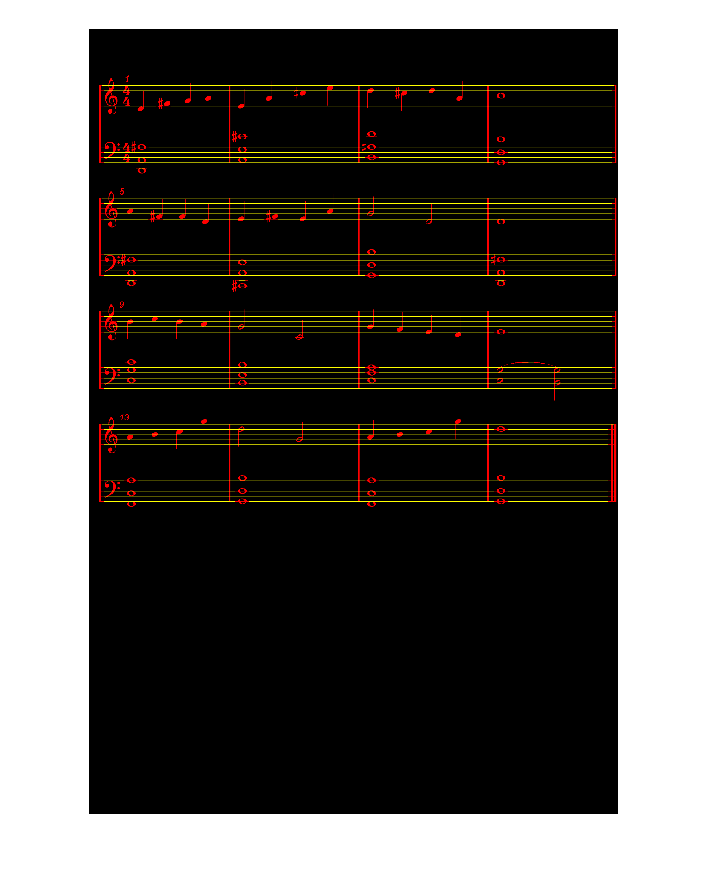

figure, imshow(cat(3,score_base*255,derivada_v*255,zeros(score_size)));

Sobre la binarització apliquem la Transformada de Hough per extreure les línies dels pentagrames. Considerem que hi caben fins a 10 parelles de pentagrames.

[m_votacio, theta, rho] = hough(derivada_v);

pics = houghpeaks(m_votacio, 100, ...
                  "Threshold",  .4* max(m_votacio(:)), ...
                  "NHoodSize", [3,3]);
linies_pentagrama = houghlines(derivada_v, theta, rho, pics, ...
                               "FillGap", score_size(2) / 3, ...
                               "MinLength", score_size(2) / 3);

linies_pentagrama_origen = reshape([linies_pentagrama.point1], [2, numel(linies_pentagrama)])';
linies_pentagrama_desti  = reshape([linies_pentagrama.point2], [2, numel(linies_pentagrama)])';


Allarguem les línies del pentagrama

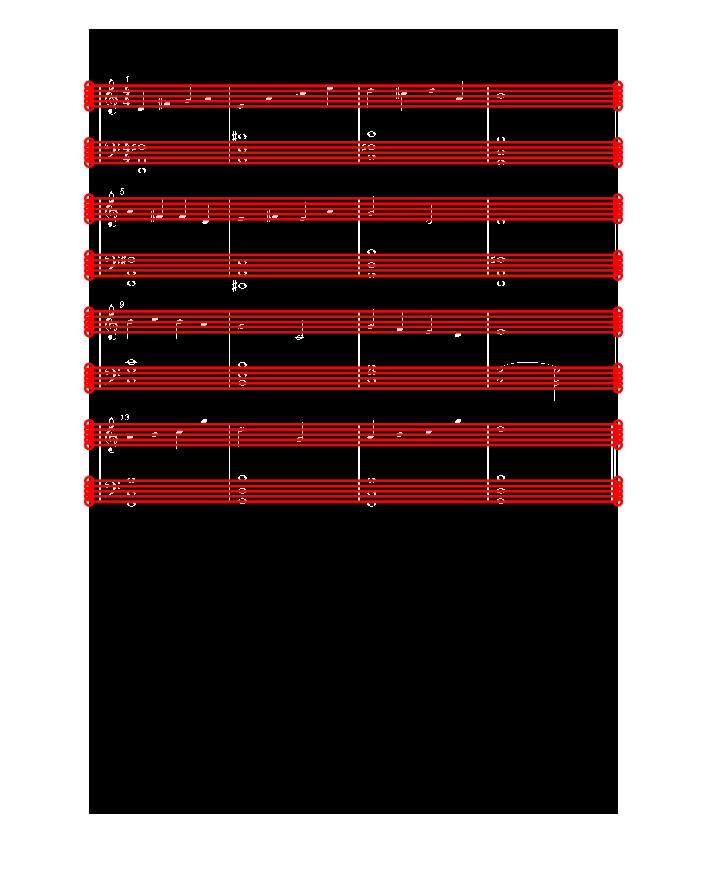

for i=1:numel(linies_pentagrama_origen(:,1))
    linies_pentagrama_origen(i,1) = 1;
    linies_pentagrama_desti(i,1) = score_size(2);
end

figure, imshow(score_base, []), hold on;
for i=1:numel(linies_pentagrama)
    plot([linies_pentagrama_origen(i,1), linies_pentagrama_desti(i,1)], ...
         [linies_pentagrama_origen(i,2), linies_pentagrama_desti(i,2)], ...
          "-r", ...
          "LineWidth", 2, ...
          "Marker","o");
    hold on;
end

Estimem l'altura de les línies a dalt i a baix de la línia trobada amb Hough.

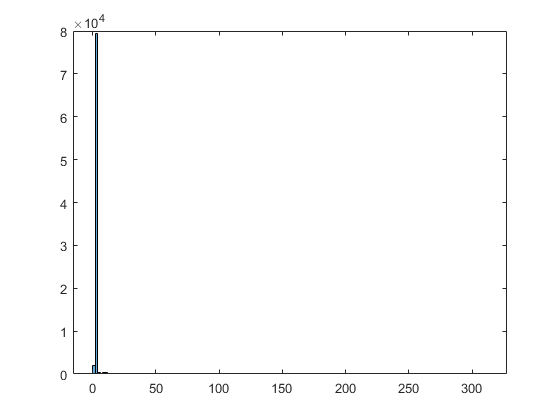

samples = zeros([score_size(2), numel(linies_pentagrama), 2]);

for l = 1:numel(linies_pentagrama)
    for i = 1:score_size(2)
        row = linies_pentagrama_desti(l,2) - linies_pentagrama_origen(l,2);
        row = int32(linies_pentagrama_origen(l,2)) + (round(row * i / score_size(2)));
        
        if score_base(row, i)
            above = 0;
            while(score_base(row - above, i))
                above = above + 1;
            end
            samples(i,l,1) = above;
            
            below = 0;
            while(score_base(row + below, i))
                below = below + 1;
            end
            samples(i,l,2) = below;
        end
    end
end

count_above = histcounts(samples(:,:,1));
count_below = histcounts(samples(:,:,2));

cumsum_above = cumsum(count_above);
cumsum_below = cumsum(count_below);

percentil_above = cumsum_above ./ cumsum_above(end);
percentil_below = cumsum_below ./ cumsum_below(end);

figure, histogram(samples(:,:,1));

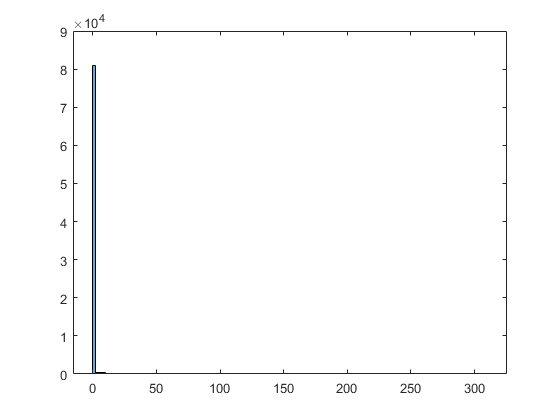

figure, histogram(samples(:,:,2));


lineheight_above = find(percentil_above > 0.8, 1, 'first') - 1;
lineheight_below = find(percentil_below > 0.8, 1, 'first') - 1;

 Eliminem el nombre de píxels corresponent en cada cas.

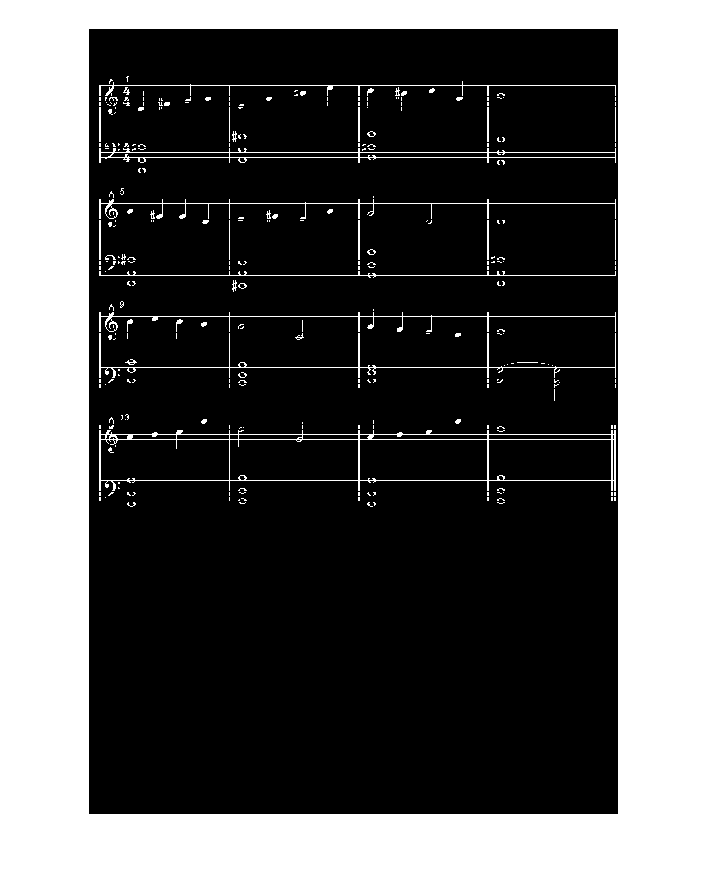

score_nocleff = score_base;
for l=1:numel(linies_pentagrama)
    for i=1:score_size(2)
        row = linies_pentagrama_desti(l,2) - linies_pentagrama_origen(l,2);
        row = int32(linies_pentagrama_origen(l,2)) + (round(row * i / score_size(2)));
        
        for height=row-lineheight_below:row+lineheight_above
            score_nocleff(height, i) = 0;
        end
    end
end

figure, imshow(score_nocleff, []);

Processar la imatge per arreglar les figures

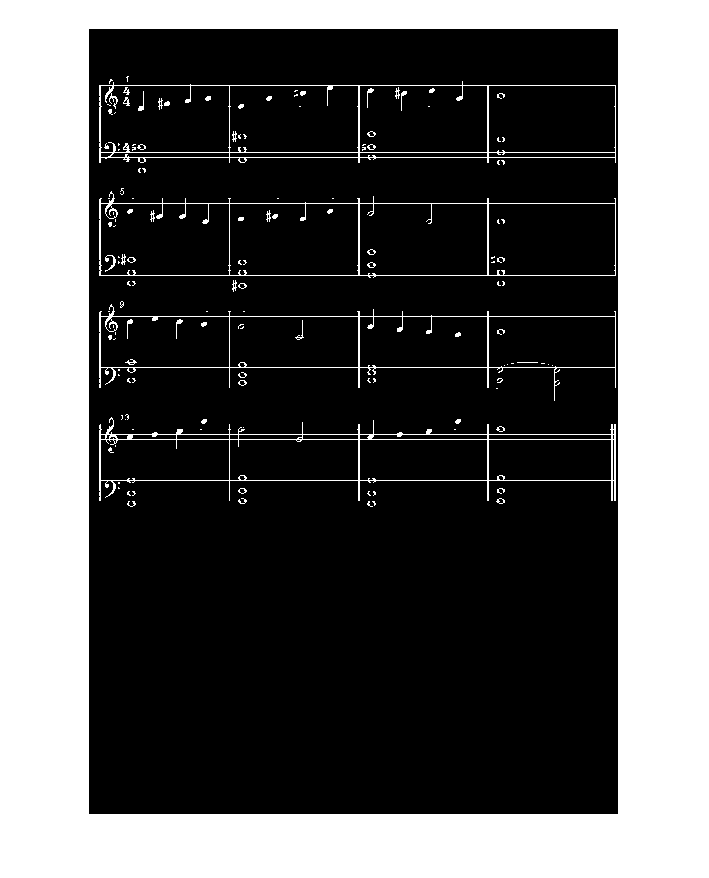

B = strel("disk", lineheight_below + lineheight_above + 1);
score_nocleff = imclose(score_nocleff, B);
score_nocleff = and(score_nocleff, score_base);

figure, imshow(score_nocleff, []);

Crear les regions de pentagrama. Estàn descrites amb la coordenada Y inicial i final (és a dir, la fila inicial i final) del bloc de pentagrames. És poc robust pel fet que agrupa línies de cinc en cinc obviant si són correctes o no. La solució més robusta es deixa per a més endavant.

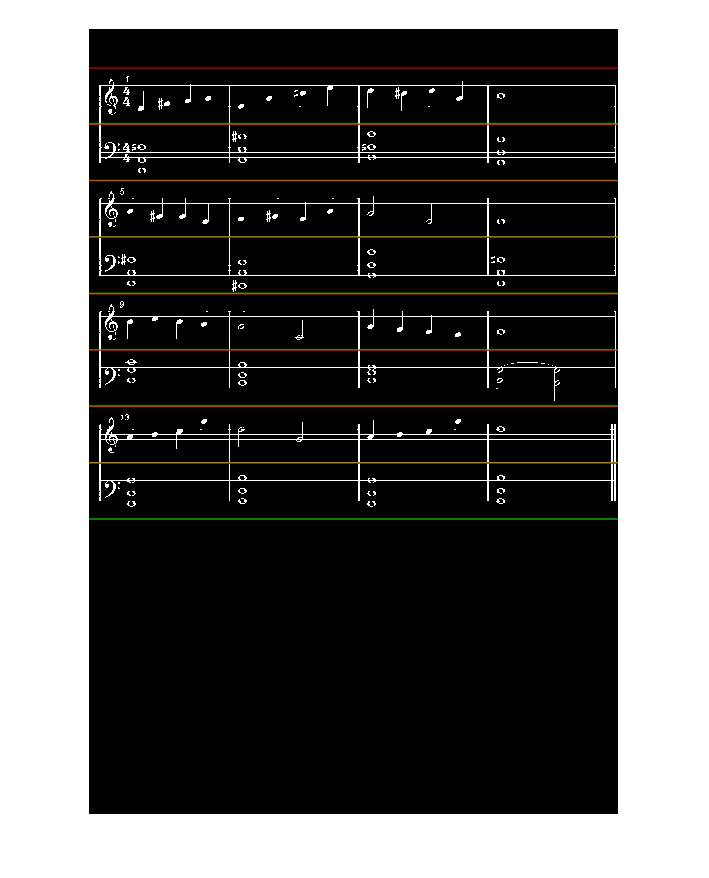

[sarray, sindex] = sort(linies_pentagrama_origen(:,2));
linies_pentagrama_origen = linies_pentagrama_origen(sindex,:);
linies_pentagrama_desti = linies_pentagrama_desti(sindex,:);

pentagrames = zeros(floor(numel(linies_pentagrama)/5), 2);

% Primer trobar les primeres i ultimes linies del pentagrama
for i=1:floor(numel(linies_pentagrama)/5)
    pentagrames(i,1) = min(linies_pentagrama_origen(((i-1)*5)+1, 2), linies_pentagrama_desti(((i-1)*5)+1,2));
    pentagrames(i,2) = max(linies_pentagrama_origen(i*5, 2), linies_pentagrama_desti(i*5,2));
end

% Trobar la minima diferencia entre linies de pentagrames diferents
mindif = inf;
for i = 1:size(pentagrames)-1
    if pentagrames(i,2) - pentagrames(i+1,1) < mindif
        mindif = pentagrames(i+1,1) - pentagrames(i,2);
    end
end

% Redefinir els limits dels pentagrames
difheight = floor(mindif/2);
for i = 1:size(pentagrames)
    pentagrames(i,1) = pentagrames(i,1) - difheight + 1;
    pentagrames(i,2) = pentagrames(i,2) + difheight - 1;
end


figure, imshow(score_nocleff), hold on;
for i = 1:size(pentagrames)
    plot([1, score_size(2)], [pentagrames(i,1) pentagrames(i,1)], '-r');
    plot([1, score_size(2)], [pentagrames(i,2) pentagrames(i,2)], '-g');
    hold on;
end